clear
T = zeros(5);
err = zeros(5);

T(2:size(T,1)-1,0+1) = 9; % left BC
T(2:size(T,1)-1,4+1) = 20; % right BC
T(0+1,2:size(T,1)-1) = 5; % lower BC
T(4+1,2:size(T,1)-1) = 136; % high BC

lambda = 1.5 % weights

lambda = 1.5000


% for n=1:11
%     n
%     tempT = T
%     for i = 2:size(T,1)-1
%         for j = 2:size(T,1)-1
%             T(i,j) = (T(i+1,j) + T(i-1,j) + T(i,j+1) + T(i,j-1))/4;
%             T(i,j) = lambda*T(i,j) + (1-lambda)*tempT(i,j);
%             err(i,j) = abs((T(i,j) - tempT(i,j))/T(i,j))*100;
%         end
%     end
%     T
%     err
%     max(err)
% end

for n=1:11
    n;
    tempT = T;
    for i = 1:size(T,1)
        for j = 1:size(T,1)
            if(i == 1)
                if(j==1)
                    T(i,j) = (T(i+1,j) + T(i,j+1))/2;
                elseif(j ==size(T,1))
                    T(i,j) = (T(i+1,j) + T(i,j-1))/2;    
                end
            elseif(i==size(T,1))
                if(j==1)
                    T(i,j) = (T(i-1,j) + T(i,j+1))/2;
                elseif(j==size(T,1))
                    T(i,j) = (T(i-1,j) + T(i,j-1))/2;
                end
            else
                if(j ~= 1 && j ~= size(T,1))
                    T(i,j) = (T(i+1,j) + T(i-1,j) + T(i,j+1) + T(i,j-1))/4;
                end
            end
            T(i,j) = lambda*T(i,j) + (1-lambda)*tempT(i,j);
            err(i,j) = abs((T(i,j) - tempT(i,j))/T(i,j))*100;
        end
    end
    T;
    err;
    max(err);
end

T6 = T

T6 =     7.0034    5.0000    5.0000    5.0000   12.5061
    9.0000   17.0902   21.4030   21.1092   20.0000
    9.0000   33.1152   42.5283   37.8612   20.0000
    9.0000   63.9398   77.5811   67.8708   20.0000
   72.5354  136.0000  136.0000  136.0000   78.0381


yi = [0 1 2 3 4].';
xi = [0 1 2 3 4].';

NewtonInterpolate(T6,xi, yi, 0.2, 2)

ans = 8.3369

NewtonInterpolate(T6,xi, yi, 0.2, 0.2)

ans = 5.6345


xplot = 0:0.1:4

xplot =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000


T_newton = zeros(size(xplot))

T_newton =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


for i = 1:size(xplot,2)
    T_newton(i) = NewtonInterpolate(T6,xi, yi, 0.2, xplot(i));
end


yi

yi =      0
     1
     2
     3
     4


xi

xi =      0
     1
     2
     3
     4


yinp = 0.2;
xinp = 0.2;
ly = ones(size(yi));
T_l = zeros(size(xplot))

T_l =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0



for i = 1:size(yi)
    for j = 1:size(yi)
        if(j ~= i)
            c = (yinp - yi(j))/(yi(i) - yi(j));
            ly(i) = ly(i)*c;
        end
    end
end

for k = 1:size(xplot,2)
    lx = ones(size(xi));
    for i = 1:size(xi)
        for j = 1:size(xi)
            if(j ~= i)
                c = (xplot(k) - xi(j))/(xi(i) - xi(j));
                lx(i) = lx(i)*c;
            end
        end
    end
    
    for i=1:5
        tempe2(i) = dot(T6(:,i),ly);
    end
    T_l(k) = dot(tempe2.',lx);
end
T_l

T_l =     5.5906    5.5826    5.6345    5.7357    5.8767    6.0483    6.2424    6.4513    6.6682    6.8867    7.1016    7.3079    7.5015    7.6791    7.8381    7.9763    8.0926    8.1863    8.2576    8.3073    8.3369    8.3486    8.3454    8.3308    8.3093    8.2859    8.2662    8.2567    8.2646    8.2977    8.3644    8.4741    8.6367    8.8629    9.1639    9.5518   10.0394   10.6401   11.3681   12.2381   13.2658


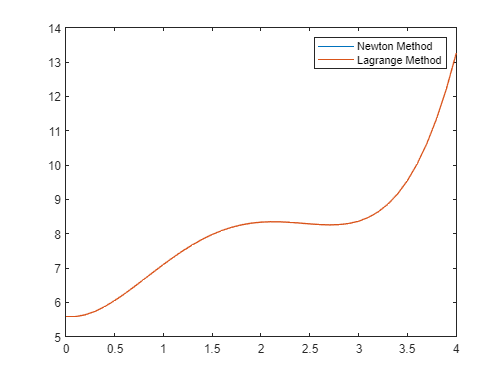


plot(xplot, T_newton)
hold on
plot(xplot, T_l)
legend('Newton Method', 'Lagrange Method')

function py = NewtonInterpolate(T6,xi, yi, yinput, xinput)
    coef = DivDiffCoef(T6,yi);
    
    p = zeros(size(T6,1),1).';
    for j = 1:size(T6)
        y = coef(:,1,j);
        px = 0;
        for i = size(T6):-1:1
            a = coef(i,i+1,j);
            px = a + (yinput - y(i)) * px;
        end
        p(j) = px;
    end
    
    yi = sort([yi; yinput]);
    idx = find(yi == yinput);
    temp = T6;
    T6(idx,:) = p;
    for i = idx:size(T6)
        T6(i+1,:) = temp(i,:);
    end
    coef = DivDiffCoef(T6.', xi);
    
    x = coef(:,1,idx);
    py = 0;
    for i = size(T6,2):-1:1
        a = coef(i,i+1,idx);
        py = a + (xinput - x(i)) * py;
    end
end

function coef = DivDiffCoef(T6,yi)
    for x = 1:size(T6,2)
        diff = zeros(size(T6));
        for y = 1:size(yi,1)
            diff(y,1) = yi(y);
            diff(y,2) = T6(y,x);
            for k=3:size(T6,1)+1
                diff(y,k) = (diff(y,k-1) - diff(k-2,k-1))/(diff(y,1) - diff(k-2,1));
            end
        end
        coef(:,:,x) = diff;
    end
end